# **Data Generation from Turboshaft Engine Model**

**For this example, we have picked the use case of a turboshaft engine with a controller, and pre-defined compressor and turbine maps. The plant model has a gas turbine consisting of compressor with a mechanically coupled turbine, whereas this rotor is aerodynamically coupled to a power turbine connected to a fan via a gearbox.**

**Now as a designer, we are allowed to change 9 design variables shown in the schematic below in order to optimize 3 system objectives:**

- Net Core Thrust (Turbine – Compressor) > 150N

- Power Turbine Thrust > 1000 N

- Rotor Shaft Mechanical Power > 5000 W

Note these are hypothetical constraints. Idea is to demonstrate the workflow for synthetic data generation, building reduced order models, and design space exploration with the help of trained AI models for different system objectives.

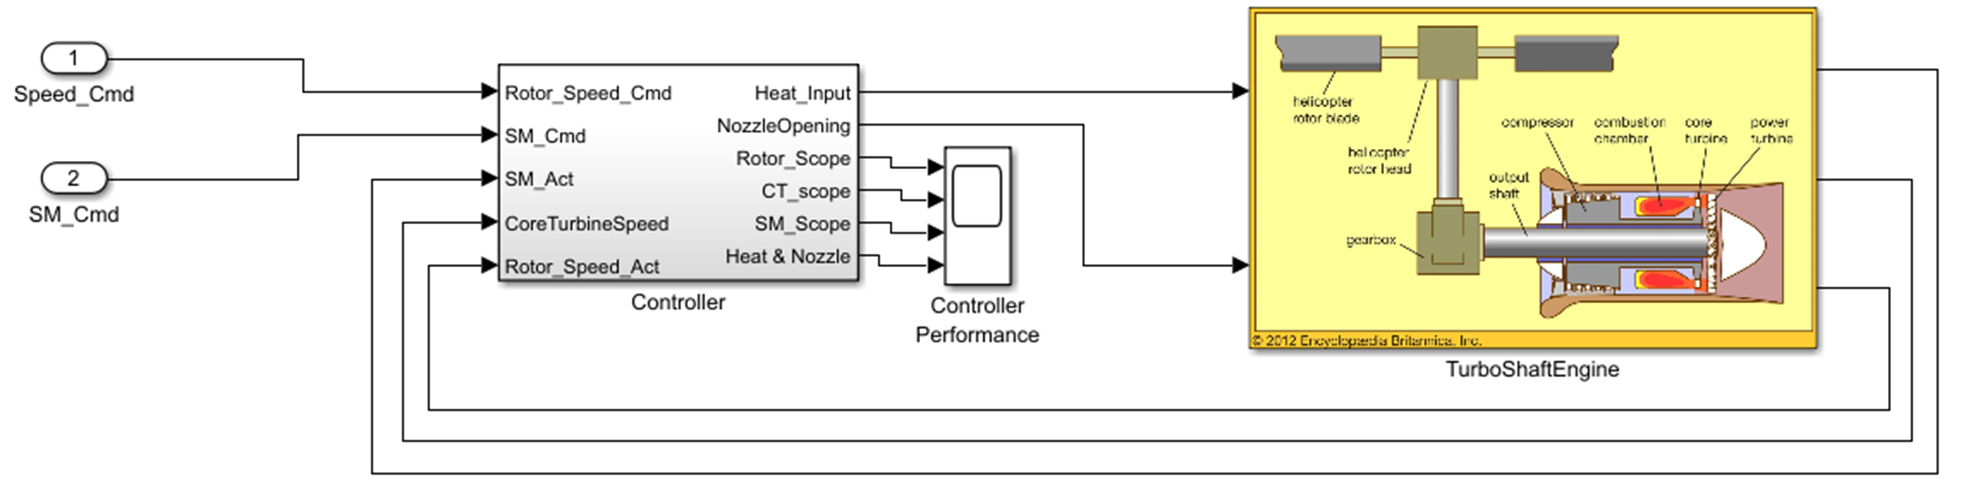

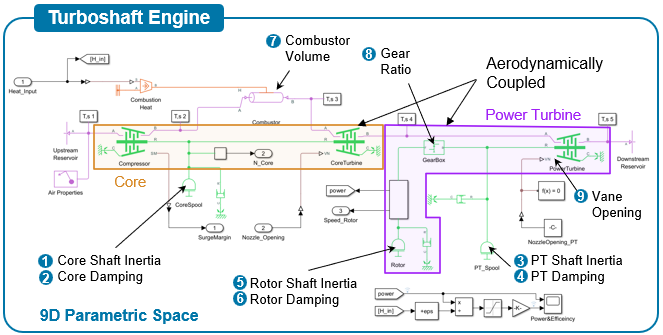

## **Latin HyperCube Sampling**

**We must approach the data generation with a systematic approach, i.e. **[**Design of Experiements**](https://www.mathworks.com/help/stats/design-of-experiments.html)**, where as a domain expert we can identify the lower and upper bounds for each design parameter. Additionally, we can decide how many simulations can we carry out from the physics-based model in limited time. **

**In statisticans words, we can run a monte-carlo simulation, or even a full factorial simulation, but we may be limited with the time and no. of simulations that we can run. So, we can go with a **[**Latin-Hypercube sampling**](https://www.mathworks.com/help/stats/lhsdesign.html)** technique, where we can decide the number of simulations that we want to run. The sampling algorithm picks up an unstructured, but nicely populated parametric space involving "n" no. of parameters as shared in this section**

rng default % For reproducibility
lhsSampling = array2table(lhsdesign(2000,9));
lhsSampling.Properties.VariableNames = {'CoreInertia','CoreDamping','CombustorVolume',...
                                        'PTInertia','RotorInertia',...
                                        'PTNozzleOpening','PTDamping','RotorDamping','GearRatio'};

**Define Lower and Upper Bounds of the Design Variables**

designVar_CoreShaftInertia_lb = 0.05;
designVar_CoreShaftInertia_ub = 0.5;
designVar_CoreDampingCoeff_lb = 0.0005;
designVar_CoreDampingCoeff_ub = 0.005;
designVar_CombustorVolume_lb = 0.001;
designVar_CombustorVolume_ub = 0.01;
% designVar_FlowArea_lb = 0.005;
% designVar_FlowArea_ub = 0.5;
designVar_PTInertiaMultiplier_lb = 0.1;
designVar_PTInertiaMultiplier_ub = 0.8;
designVar_RotorInertiaMultiplier_lb = 0.1;
designVar_RotorInertiaMultiplier_ub = 0.8;
designVar_PTNozzleOpening_lb = 0.3;
designVar_PTNozzleOpening_ub = 1.0;
designVar_PTDampingCoeff_lb = 0.0005;
designVar_PTDampingCoeff_ub = 0.005;
designVar_RotorDampingCoeff_lb = 0.0005;
designVar_RotorDampingCoeff_ub = 0.005;
designVar_GearRatio_lb = 1.5;
designVar_GearRatio_ub = 6;

**Design Variable Table**

designVars = lhsSampling;
format short
designVars.CoreInertia = designVar_CoreShaftInertia_lb + lhsSampling.CoreInertia * (designVar_CoreShaftInertia_ub - designVar_CoreShaftInertia_lb);
designVars.CoreDamping = designVar_CoreDampingCoeff_lb + lhsSampling.CoreDamping * (designVar_CoreDampingCoeff_ub - designVar_CoreDampingCoeff_lb);
designVars.CombustorVolume = designVar_CombustorVolume_lb + lhsSampling.CombustorVolume * (designVar_CombustorVolume_ub - designVar_CombustorVolume_lb);
% designVars.FlowArea = designVar_FlowArea_lb + lhsSampling.FlowArea * (designVar_FlowArea_ub - designVar_FlowArea_lb);
designVars.PTInertia = designVars.CoreInertia .* (designVar_PTInertiaMultiplier_lb + lhsSampling.PTInertia * (designVar_PTInertiaMultiplier_ub - designVar_PTInertiaMultiplier_lb));
designVars.RotorInertia = designVars.CoreInertia .* (designVar_RotorInertiaMultiplier_lb + lhsSampling.RotorInertia * (designVar_RotorInertiaMultiplier_ub - designVar_RotorInertiaMultiplier_lb));
designVars.PTNozzleOpening = designVar_PTNozzleOpening_lb + lhsSampling.PTNozzleOpening * (designVar_PTNozzleOpening_ub - designVar_PTNozzleOpening_lb);
designVars.PTDamping = designVar_PTDampingCoeff_lb + lhsSampling.PTDamping * (designVar_PTDampingCoeff_ub - designVar_PTDampingCoeff_lb);
designVars.RotorDamping = designVar_RotorDampingCoeff_lb + lhsSampling.RotorDamping * (designVar_RotorDampingCoeff_ub - designVar_RotorDampingCoeff_lb);
designVars.GearRatio = designVar_GearRatio_lb + lhsSampling.GearRatio * (designVar_GearRatio_ub - designVar_GearRatio_lb);
summary(designVars)

Variables:
    CoreInertia: 2000×1 double
        Values:
            Min       0.05001 
            Median    0.27509 
            Max       0.49982 
    CoreDamping: 2000×1 double
        Values:
            Min       0.00050217
            Median     0.0027501
            Max        0.0049987
    CombustorVolume: 2000×1 double
        Values:
            Min        0.001001
            Median    0.0054997
            Max       0.0099994
    PTInertia: 2000×1 double
        Values:
            Min       0.0057988
            Median      0.10571
            Max         0.37768
    RotorInertia: 2000×1 double
        Values:
            Min       0.0071394
            Median      0.10475
            Max         0.39243
    PTNozzleOpening: 2000×1 double
        Values:
            Min       0.30006 
            Median    0.64997 
            Max       0.99987 
    PTDamping

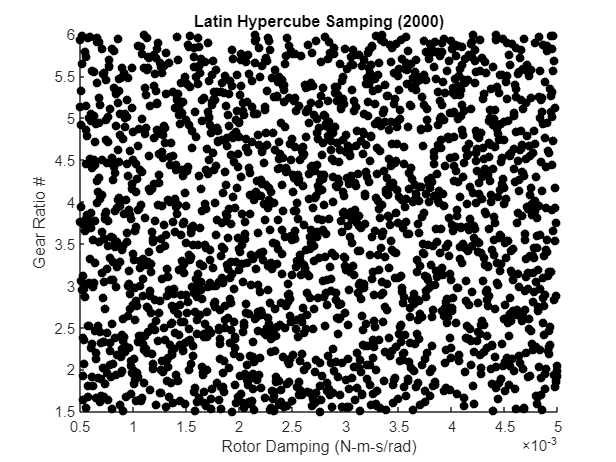

figure
scatter(designVars.RotorDamping,designVars.GearRatio,'k','filled')
xlabel('Rotor Damping (N-m-s/rad)')
ylabel('Gear Ratio #')
title('Latin Hypercube Samping (2000)')

**Speed & Surge Margin inputs for the controller in simulation model**

t = (0:1:1200)'; % time from 0 sec to 1200 sec

Ramp & Hold the speed

rpm = (0:20:12000)'; % Linear Ramp 
rpm = [rpm; ones(height(t)-height(rpm),1)*12000]; % Concatenate Linear Ramp with Hold

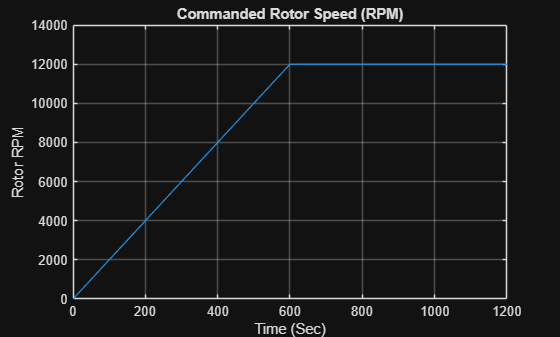

plot(t,rpm)
xlabel('Time (Sec)')
ylabel('Rotor RPM')
ylim([0 14000])
grid on
title ('Commanded Rotor Speed (RPM)')

sm = ones(size(t))*0.2; % Surge Margin
u = [rpm sm]; % Input matrix for simulation model

## Set Up Simulation

Set up the [`Simulink.SimulationInput`](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) object for each unique simulation.  Here we will set the variables that are changing for each iteration.  

**Note:** The loop is running backward to dynamically preallocate the data type.

for ii = height(designVars):-1:1
    simIn (ii) = Simulink.SimulationInput('TurboShaftEngine_mod');
    simIn (ii) = simIn (ii).setVariable('Core_Shaft_inertia',designVars.CoreInertia(ii));
    simIn (ii) = simIn (ii).setVariable('Core_Damping_Coeff',designVars.CoreDamping(ii));%designVars.CoreDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('Combustor_volume',designVars.CombustorVolume(ii));
    simIn (ii) = simIn (ii).setVariable('Flow_area',0.01);%designVars.FlowArea(ii), default 0.01
    simIn (ii) = simIn (ii).setVariable('PT_Shaft_inertia',designVars.PTInertia(ii));
    simIn (ii) = simIn (ii).setVariable('PT_Nozzle_Opening',designVars.PTNozzleOpening(ii));
    simIn (ii) = simIn (ii).setVariable('PT_Damping_Coeff',designVars.PTDamping(ii));%designVars.PTDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('Rotor_Damping_Coeff',designVars.RotorDamping(ii));%designVars.RotorDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('GearRatio',designVars.GearRatio(ii));
    simIn (ii) = simIn (ii).setVariable('Rotor_Inertia',designVars.RotorInertia(ii));
end

try
    out = parsim(simIn , 'TransferBaseWorkspaceVariables', 'on', 'ShowProgress', true, 'UseFastRestart', false,'ShowSimulationManager','on')
catch ME
    fprintf('An error occurred during simulation: %s\n', ME.message);
end

[14-Feb-2024 20:41:23] Checking for availability of parallel pool...
[14-Feb-2024 20:41:23] Starting Simulink on parallel workers...
[14-Feb-2024 20:41:24] Configuring simulation cache folder on parallel workers...
[14-Feb-2024 20:41:24] Transferring base workspace variables used in the model to parallel workers...
[14-Feb-2024 20:41:40] Loading model on parallel workers...
[14-Feb-2024 20:42:01] Running simulations...


[14-Feb-2024 23:26:56] Cleaning up parallel workers...


out = 1x2000 Simulink.SimulationOutput array



save lhs2000.mat out simIn

## **Test Run (for Hands-on Workshop)**

simIn (1) = Simulink.SimulationInput('TurboShaftEngine_mod');
simIn (1) = simIn (1).setVariable('Core_Shaft_inertia',0.1);
simIn (1) = simIn (1).setVariable('Core_Damping_Coeff',0.001);
simIn (1) = simIn (1).setVariable('Combustor_volume',0.01);
simIn (1) = simIn (1).setVariable('Flow_area',0.01);
simIn (1) = simIn (1).setVariable('PT_Shaft_inertia',0.1/3);
simIn (1) = simIn (1).setVariable('PT_Nozzle_Opening',0.5);
simIn (1) = simIn (1).setVariable('PT_Damping_Coeff',0.001);
simIn (1) = simIn (1).setVariable('GearRatio',6);
simIn (1) = simIn (1).setVariable('Rotor_Inertia',0.02);
simIn (1) = simIn (1).setExternalInput([t u]);
outTest = parsim(simIn(1))

[16-Jul-2025 19:15:44] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
16-Jul-2025 19:16:59: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 4 workers.
[16-Jul-2025 19:17:19] Starting Simulink on parallel workers...
[16-Jul-2025 19:17:43] Configuring simulation cache folder on parallel workers...
[16-Jul-2025 19:17:43] Loading model on parallel workers...
[16-Jul-2025 19:18:03] Running simulations...
[16-Jul-2025 19:19:03] Completed 1 of 1 simulation runs
[16-Jul-2025 19:19:03] Received simulation output (size: 13.00 KB) for run 1 from parallel worker.
[16-Jul-2025 19:19:04] Cleaning up parallel workers...


outTest =   Simulink.SimulationOutput:

                     logsout: [1x1 Simulink.SimulationData.Dataset] 
     simlog_TurboShaftEngine: [1x1 simscape.logging.Node] 
                        tout: [275x1 double] 

          SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
                ErrorMessage: [0x0 char] 


% Core_Shaft_inertia = 0.1; %default 0.1
% Core_Damping_Coeff = 0.001; %default 0.001
% Combustor_volume = 0.01; %default 0.001
% Flow_area = 0.01; %default 0.01
% PT_Shaft_inertia = Core_Shaft_inertia/3; %default I/5
% PT_Nozzle_Opening = 0.5; %default 0.5
% PT_Damping_Coeff = 0.001; %default 0.001
% GearRatio = 6; %default 6.0
% Rotor_Inertia = Core_Shaft_inertia/5; %default I/10

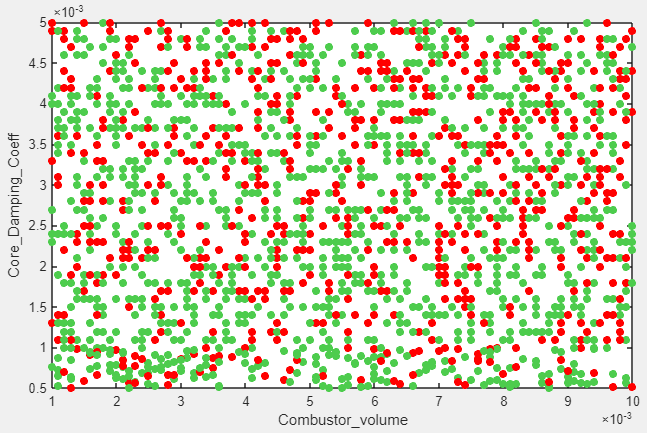

1262 successful runs out of 2000

**Log Simulation Results into Data Table**

j=1;
for i=1:height(out')
    if isempty(out(1,i).ErrorMessage)
        Time = timeseries2timetable(out(1,i).logsout{1}.Values).Time;
        heatInput = timeseries2timetable(out(1,i).logsout{1}.Values);
        nozzleOpening = timeseries2timetable(out(1,i).logsout{2}.Values);
        power = timeseries2timetable(out(1,i).logsout{3}.Values);
        efficiency = timeseries2timetable(out(1,i).logsout{4}.Values);
        % Simscape Results
        fullResults = out(1, i).simlog_TurboShaftEngine.TurboShaftEngine;
        
        CoreTurbine_FluidPower = values(fullResults.CoreTurbine.fluid_power.series);
        Compressor_FluidPower = values(fullResults.Compressor.fluid_power.series);
        CorePower = (CoreTurbine_FluidPower - Compressor_FluidPower)*1000; % in Watts or N-m/sec
        TurbineOutletVelocity = abs(values(fullResults.CoreTurbine.outlet_velocity.series)); % in m/sec
        Thrust_Core = CorePower ./ TurbineOutletVelocity;

        PT_FluidPower = values(fullResults.PowerTurbine.fluid_power.series)*1000; % in Watts or N-m/sec
        PTOutletVelocity = abs(values(fullResults.PowerTurbine.outlet_velocity.series)); % in m/sec
        Thrust_PT = PT_FluidPower ./ PTOutletVelocity;

        Thrust_Net = Thrust_Core+Thrust_PT;
        Thrust_Net = table(Time, Thrust_Net);
        Thrust_Net = table2timetable(Thrust_Net);

        Thrust_PT = table2timetable(table(Time, Thrust_PT));
        Thrust_Core = table2timetable(table(Time, Thrust_Core));


        simOut(j,1:8) = table(i,{heatInput},{nozzleOpening},{power},{efficiency},...
                              {Thrust_Core},{Thrust_PT},{Thrust_Net});

        j=j+1;
    end
end
simOut.Properties.VariableNames = {'RunID','HeatInput_kW','TurbineNozzleOpening','ShaftPower_kW','ShaftMechEfficiency','Thrust','ThrustPT','ThrustNet_N'};
designVariables = designVars(simOut.RunID,:); % Only retain succesful execution from the DOE

save DOE_LHS2000 designVariables simOut t u rpm sm

## Open Results from a **specific RunID**

**For the hands-on workshop, set the runID value to 1, and "out" variable to "outTest"**

runID = 1;
Time = timeseries2timetable(outTest(1,runID).logsout{1}.Values).Time;
fullResults = outTest(1, runID).simlog_TurboShaftEngine.TurboShaftEngine;

PT_FluidPower = values(fullResults.PowerTurbine.fluid_power.series);
CoreTurbine_FluidPower = values(fullResults.CoreTurbine.fluid_power.series);
Compressor_FluidPower = values(fullResults.Compressor.fluid_power.series);

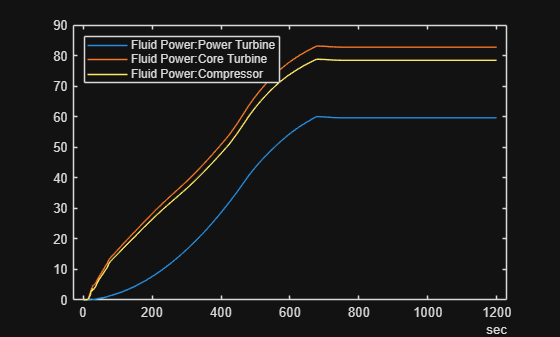

figure
plot(Time,PT_FluidPower)
hold on
plot(Time,CoreTurbine_FluidPower)
plot(Time,Compressor_FluidPower)
legend('Fluid Power:Power Turbine','Fluid Power:Core Turbine','Fluid Power:Compressor','Location','northwest')

CorePower = (CoreTurbine_FluidPower - Compressor_FluidPower)*1000; % in Watts or N-m/sec
TurbineOutletVelocity = abs(values(fullResults.CoreTurbine.outlet_velocity.series)); % in m/sec
Thrust_Core = CorePower ./ TurbineOutletVelocity;
PTOutletVelocity = abs(values(fullResults.PowerTurbine.outlet_velocity.series)); % in m/sec
Thrust_PT = PT_FluidPower*1000 ./ PTOutletVelocity;
NetThrust = Thrust_Core+Thrust_PT;

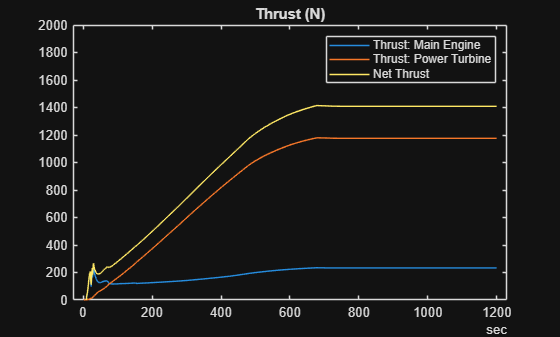

figure
plot(Time,Thrust_Core)
hold on
plot(Time,Thrust_PT)
plot(Time,NetThrust)
title('Thrust (N)')
ylim([0 2000])
legend('Thrust: Main Engine','Thrust: Power Turbine','Net Thrust')